[values, best, bestReturn] = main;
best

best = 1.0e+06 *

    0.0000    2.4975    2.4888    2.5082    2.5055


fprintf("vynos investicii je: %d", bestReturn)

vynos investicii je: 7.243570e+05

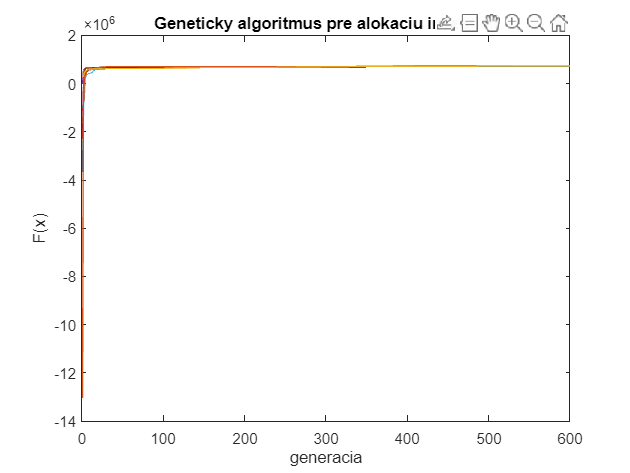


plot(values)
hold on
title('Geneticky algoritmus pre alokaciu investicii');
xlabel('generacia');
ylabel('F(x)');

**Pokuta cislo 1:**  $x_1 +x_2 +x_3 +x_4 +x_5 \le 10\;000\;000$

navratova hodnota je matica 1x1

function [value] = violation1(vector)
    value = sum(vector);
    if (value <= 10000000)
        value = 0;
    end
end

**Pokuta cislo 2: **$x_1 +x_2 \le 2\;500\;000$

navratova hodnota je matica 1x1

function [value] = violation2(vector)
    value = sum(vector);
    if(value <= 2500000)
        value = 0;
    end
end

**Pokuta cislo 3: **${-x}_4 +x_5 \le 0$

navratova hodnota je matica 1x1

function [value] = violation3(vector)
    value = vector(2)-vector(1);
    if(value <= 0)
        value = 0;
    end
end

**Pokuta cislo 4:**  $-0\ldotp 5x_1 -{0\ldotp 5x}_2 +{0\ldotp 5x}_3 +{0\ldotp 5x}_4 -{0\ldotp 5x}_5 \le 0$

navratova hodnota je matica 1x1

function [value] = violation4(vector)
    value = -vector(1) - vector(2) + vector(3) + vector(4) - vector(5);
    if(value <= 0)
        value = 0;
    end
end

**fitness funkcia** na vypocet hodnoty jedinca pomocou `mrtvej pokuty`

navratova hodnota je matica rozmeru m x 1 -------> v tomto pripade 100x1

function[values] = deathPenalty(moneyMatrix)
    [m,~]=size(moneyMatrix);
    values = zeros(m, 1);
    for i=1:m
        if(violation1(moneyMatrix(i,:)) ~= 0 || violation2(moneyMatrix(i, 1:2)) ~= 0 || violation3(moneyMatrix(i, 4:5)) ~= 0 || violation4(moneyMatrix(i,:)) ~= 0) 
        bill = -intmax("uint32");        %18 446 744 073 709 551 615
        else
        bill = 0;
        end
        values(i)=-(0.04*moneyMatrix(i,1)+0.07*moneyMatrix(i,2)+0.11*moneyMatrix(i,3)+0.06*moneyMatrix(i,4)+0.05*moneyMatrix(i,5))+bill;
        
    end
end

**fitness funkcia** na vypocet hodnoty jedinca pomocou `stupnovitej pokuty`

navratova hodnota je matica rozmeru m x 1 -------> v tomto pripade 100x1

function[values] = degreePenalty(moneyMatrix)
    [m,~]=size(moneyMatrix);
    values = zeros(m, 1);
    
    for i=1:m
        degree = 0;
        if(violation1(moneyMatrix(i,:))~=0)
            degree = degree + 1;
        end
        if(violation2(moneyMatrix(i, 1:2))~=0)
            degree = degree + 1;
        end
        if(violation3(moneyMatrix(i, 4:5))~=0)
            degree = degree + 1;
        end
        if(violation4(moneyMatrix(i,:))~=0)
            degree = degree + 1;
        end
        bill = 10^7 * degree;
        values(i)=-(0.04*moneyMatrix(i,1)+0.07*moneyMatrix(i,2)+0.11*moneyMatrix(i,3)+0.06*moneyMatrix(i,4)+0.05*moneyMatrix(i,5))+bill;
    end
end

**fitness funkcia** na vypocet hodnoty jedinca pomocou `pokuty umernej miere porusenia`

navratova hodnota je matica rozmeru m x 1 -------> v tomto pripade 100x1

function[values] = topInvesticia(moneyMatrix)
    [m,~]=size(moneyMatrix);
    values = zeros(m, 1);
    for i=1:m
        bill = 0 + violation1(moneyMatrix(i,:)) + violation2(moneyMatrix(i, 1:2)) + ...
        + violation3(moneyMatrix(i, 4:5)) + violation4(moneyMatrix(i,:));
        values(i)=-(0.04*moneyMatrix(i,1)+0.07*moneyMatrix(i,2)+0.11*moneyMatrix(i,3)+0.06*moneyMatrix(i,4)+0.05*moneyMatrix(i,5))+bill;
    end
end

**funkcie na krizenie** a mutovanie matic (investicii)

navratova hodnota je matica rovnakeho rozmeru ako vstupna matica

function [matrix] = cross_mut(matrix, space)
    matrix = crossov(matrix, 4, 0);
    matrix = muta(matrix, 0.15, space(2,:)/250, space);
end

function [matrix] = cross_mut2(matrix, space)
    matrix = crossov(matrix, 1, 0);
    matrix = muta(matrix, 0.2, space(2,:)/250, space);
    matrix = crossov(matrix, 1, 0);
    matrix = mutx(matrix, 0.1, space);
end

hlavna funkcia v ktorej:

generujem maticu vektorov a hodnotami investicie od 0 po 10 000 000

vo for cykle 

function [bestInv, bestvector, bestVal] = main()
beh = 600;
rangeOfValues = [zeros(1, 5); ones(1, 5) * 10000000];
investitionRows = genrpop(500, rangeOfValues);
bestInv = zeros(beh,1);
for i = 1:beh
    fitFun = topInvesticia(investitionRows);
    bestInv(i) = -1 * min(fitFun);
    part1 = selbest(investitionRows, fitFun, 60);
    part2 = seltourn(investitionRows, fitFun, 60);
    part6 = selrand(investitionRows, fitFun, 60);
    part7 = selsus(investitionRows, fitFun, 20);

    part3 = investitionRows(201:300, :);            %random vyber na roznorodost populacie
    part4 = investitionRows(1:100, :);              %random vyber na roznorodost populacie
    part5 = genrpop(100, rangeOfValues);            %nova generacia na roznorodost populacie
    
    
%prve krizenie + mutovanie

    part2 = cross_mut(part2, rangeOfValues);
    part3 = cross_mut(part3, rangeOfValues);
    %part5 = cross_mut(part5, rangeOfValues);

%druhe krizenie + mutovanie

    part4 = cross_mut2(part4, rangeOfValues);
    part6 = cross_mut2(part6, rangeOfValues);
    part7 = cross_mut2(part7, rangeOfValues);

    investitionRows = [part1; part2; part3; part4; part5; part6; part7];
end

fitFun = topInvesticia(investitionRows);
bestInv(i) = -1 * min(fitFun);
bestvector = selbest(investitionRows, fitFun, 1);
bestVal = max(bestInv);
end